clear

### **Note: If your results turn out unexpected, like fx negative even if expected positive - do a static analysis with the moment equation - sizing decisions can lead the forklift to be not in equilibrium when in standstill!**

# DaFork - Dynamics analysis

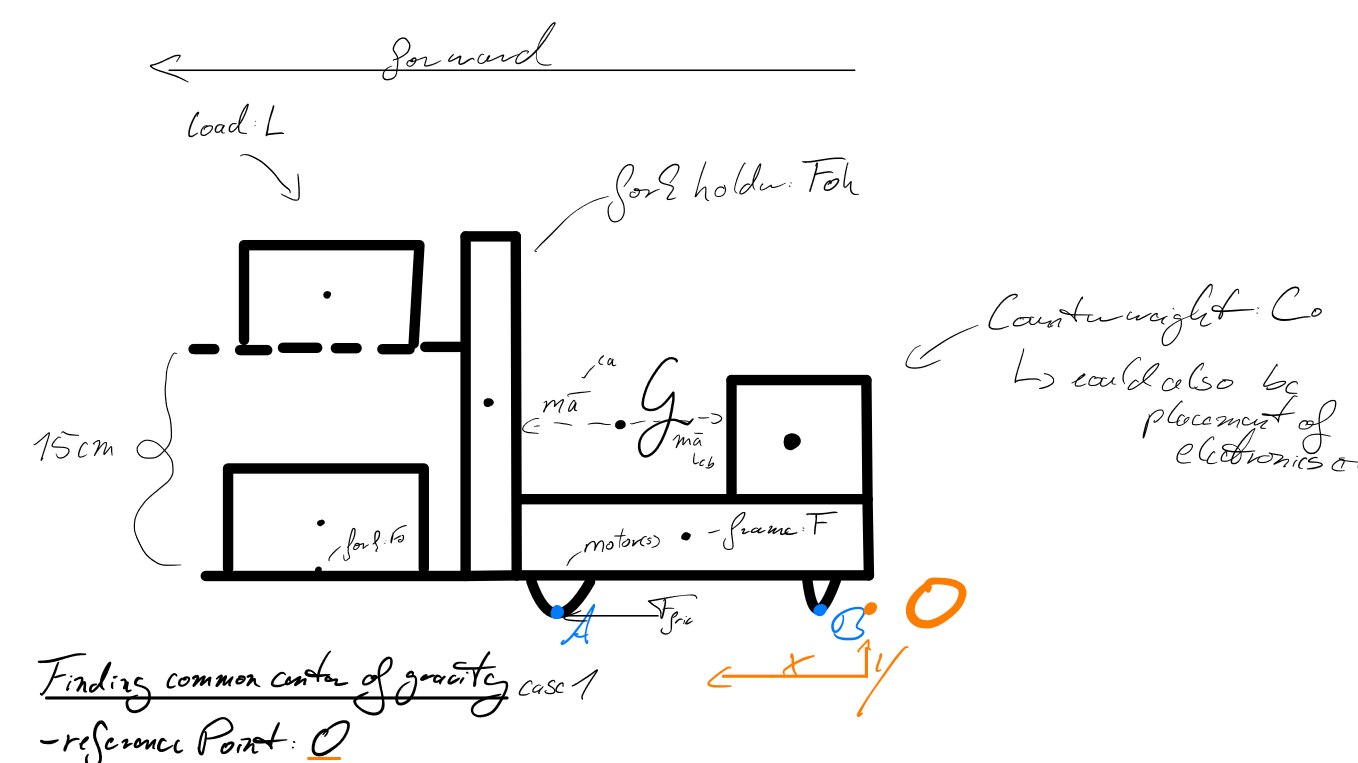

**Declaration of goals of this script**

- Checking fullfillment of specified requirements

- Determine risk of tilting --> Determine design limitations 

- Design considerations: Position of mass, maximum speed allowed, length and width of forklift

- Getting a gist of motor sizing

**Implemented functionality**

- Calculation of center of gravity

- Determine Stability - not moving

- Finding maximum back and forward accelerations, fork down and up

# **Declaration of requirements**

- The desired driving speed is 5 cm/s

- The desired maximum lifting weight is 3.5 kg

- The desired maximum distance to reach operating speed is 5 cm

syms desired_speed desired_lift_weight desired_acceleration_distance s needed_acceleration
desired_speed = 100 * 10^-3 % m/s --> 10 cm/s

desired_speed = 0.1000

desired_lift_weight = 3.5 % kg

desired_lift_weight = 3.5000

desired_acceleration_distance = 50 * 10^-3 % m

desired_acceleration_distance = 0.0500

desired_lifting_height = 150 * 10^-3 % m --> 15cm

desired_lifting_height = 0.1500

**Assumptions**

- Rolling without slipping

- Center of gravity is estimated by finding the common center of gravity of the combined body

- Certain symetries.

- Load is placed in the middle of the fork

- Even surface with no incline

What is the acceleration needed to reach desired speed in specified distance?

needed_acceleration = vpasolve(desired_speed^2 - 0^2 == 2 * needed_acceleration * (desired_acceleration_distance), needed_acceleration)

$$needed\_acceleration = 0.1$$


sprintf('To reach the operating speed of %f m/s an acceleration of %f m/s^2 is required', desired_speed, needed_acceleration)

ans = 'To reach the operating speed of 0.100000 m/s an acceleration of 0.100000 m/s^2 is required'


% Time to reach desired speed in s
desired_speed / needed_acceleration

$$ans = 1.0$$

So the motortorque and wheelsize have to be chosen accordingly.

For further calculations the **center of gravity** of the combined body (the forklift) has to be found. For this the forklift is split into the following sections: Fork, Forkholder Load, Frame and Counterweight which includes (for now) also the electronics. Further sections can easily be added. For example adding motors.

Just keep in mind that if sections are added they also have to be added to the center of gravity calculations. But that is relatively easy.

# **Dimensions of DaFork**

For now arbitrary chosen - sizes are referenced to free-body diagram in the DaForkDynamics.pdf

length = x-axis

height = y-axis

reference point is: O

**Weights are estimated and have to be adjusted!!!**

% Frame
frame_length = 250 * 10^-3 % m --> 25cm

frame_length = 0.2500

frame_height = 6 * 10^-3 % m --> 6mm 

frame_height = 0.0060

frame_mass = 3 % kg 

frame_mass = 3


frame_offset = 27 * 10^-3 % m --> 2.7cm meaning how much the frame/body is over the ground

frame_offset = 0.0270



% Fork and Load -- Forkholder == Mast
fork_length = 150 * 10^-3 % m --> 15cm

fork_length = 0.1500

forkholder_length = 70 * 10^-3 % m --> 5cm

forkholder_length = 0.0700

forkholder_heigth = 250 * 10^-3 % m --> 25cm

forkholder_heigth = 0.2500


fork_mass = 0.3 % kg

fork_mass = 0.3000

fork_holder_mass = 0.7 % kg

fork_holder_mass = 0.7000


load_length = 150 * 10^-3 % m --> 15cm

load_length = 0.1500

load_height = 150 * 10^-3 % m --> 15cm meaning height of cans

load_height = 0.1500

load_mass = desired_lift_weight % kg

load_mass = 3.5000


% Counterweight + Components
counterweight_length = 100 * 10^-3 % m --> 10cm

counterweight_length = 0.1000

counterweight_heigth = 100 * 10^-3 % m --> 10cm

counterweight_heigth = 0.1000

counterweight_mass = 5 % kg

counterweight_mass = 5


% Wheels - Wheel A is/are the driven wheel(s) Wheel B is support
Wheel_A_distance = 232.3 * 10^-3 % m --> 35cm, meaning the distance on x-axis from point O

Wheel_A_distance = 0.2323

Wheel_B_distance = 50 * 10^-3 % m --> 5cm, meaning the distance on x-axis from point O

Wheel_B_distance = 0.0500


Wheel_A_B_distance = Wheel_A_distance - Wheel_B_distance

Wheel_A_B_distance = 0.1823




Wheel_A_radius = 30 * 10^-3 % m --> 3cm

Wheel_A_radius = 0.0300

Wheel_A_mass = 200 * 10^-3 % kg --> 200g

Wheel_A_mass = 0.2000

Wheel_A_count = 2

Wheel_A_count = 2

Wheel_A_I = Est_I_CylZ(Wheel_A_mass,Wheel_A_radius) % Moment of inertia

Wheel_A_I = 9.0000e-05


% Distance of the pair of wheels
Wheel_A_axis_lenth = 198 * 10^-3 % m --> 19.8cm

Wheel_A_axis_lenth = 0.1980


Wheel_B_radius = 30 * 10^-3 % m --> 3cm

Wheel_B_radius = 0.0300

Wheel_B_mass = 200 * 10^-3 % kg --> 200g

Wheel_B_mass = 0.2000

Wheel_B_count = 1

Wheel_B_count = 1

Wheel_B_I = Est_I_CylZ(Wheel_B_mass,Wheel_B_radius) % Moment of inertia

Wheel_B_I = 9.0000e-05

# **Moments of Inertia of body parts**

**Moment of Inertia is calculated with respect to axis of rotation**

**with the help of the parallel axis theorem**

frame_Gx = abs(Wheel_A_distance - (frame_length / 2))

frame_Gx = 0.1073

frame_I = frame_mass * frame_Gx^2 + Est_I_BlockGxx(frame_mass, frame_length, frame_height)

frame_I = 0.0398


counterweight_Gx = abs(Wheel_A_distance - (counterweight_length / 2))

counterweight_Gx = 0.1823

counterweight_I = counterweight_mass * counterweight_Gx^2 + Est_I_BlockGxx(counterweight_mass, counterweight_length, counterweight_heigth)

counterweight_I = 0.1678


load_Gx = abs(Wheel_A_distance - (load_length / 2))

load_Gx = 0.1573

load_I = load_mass * load_Gx^2 + Est_I_BlockGxx(load_mass, load_length, load_height)

load_I = 0.0904


DaFork_I = frame_I + counterweight_I + load_I

DaFork_I = 0.2979

# **Center of gravity of DaFork**


% Applying eqs for common center of gravity

DaFork_mass = frame_mass + fork_mass + load_mass + counterweight_mass

DaFork_mass = 11.8000


sprintf('Common center of gravity:')

ans = 'Common center of gravity:'


X_O = (load_mass * (fork_length/2 + forkholder_length + frame_length) + fork_mass * (fork_length/2 + forkholder_length + frame_length) + fork_holder_mass * (forkholder_length/2 + frame_length)+ frame_mass * (frame_length/2) + counterweight_mass * (counterweight_length / 2)) / (DaFork_mass)

X_O = 0.1971

% case 1: fork down, case 2: fork up
Y_Oc1 = (load_mass * (load_height/2 + frame_offset) + fork_mass * (frame_offset) + fork_holder_mass * (forkholder_heigth/2 + frame_offset) + frame_mass * (frame_height/2 + frame_offset) + counterweight_mass * (counterweight_heigth/2 + frame_height + frame_offset)) / (DaFork_mass)

Y_Oc1 = 0.0828

Y_Oc2 = (load_mass * (load_height/2 + desired_lifting_height + frame_offset) + fork_mass * (desired_lifting_height + frame_offset) + fork_holder_mass * (forkholder_heigth/2 + frame_offset) + frame_mass * (frame_height/2 + frame_offset) + counterweight_mass * (counterweight_heigth/2 + frame_height + frame_offset) ) / (DaFork_mass)

Y_Oc2 = 0.1311

# **Determine Stability - not moving**

if X_O > Wheel_A_distance
    sprintf('Unstable! The forklift would tilt!')
end
if X_O < Wheel_B_distance
    sprintf('Unstable! The forklift would tilt!')
end

# **Calculations for case 1: Fork down**

What is the maximum acceleration allowed before tilting?

For reference directions check pdf:

- Forwards: direction of fork

- Backwards: direction of backwheel "pulling the fork behind the vehicle"

- Point A sits on the driving wheel(s)

- Point B sits on the backwheel(s)

In both variations we have the following forces

- Normal forces in point A and B

- Gravity on the common center of gravity

- Friction force on the driving wheel(s)

- --> for now we consider a purely 2D-model, if we have 2 motors we just have to divide the friction force by two when looking for the required motor torque

**Driving/Accelerating forward: case 1a --> finding max acceleration forwards**

syms a_bar_x Na Nb

a_bar_y = 0;
g = 9.81;
d_c1 = Y_Oc1

d_c1 = 0.0828


% Equation used: Sum(Mp) = I-bar * alpha + m * a_bar * d
% Assumption no tipping --> alpha = 0
% choosing a convenient reference point A - this way we don´t have to deal with Ffric 

% Equation pf Moment // Reference Counterclockwise
if X_O > Wheel_A_distance
    eq_M_A_c1a = Nb * Wheel_A_B_distance + DaFork_mass * g * (X_O - Wheel_A_distance) == DaFork_mass * a_bar_x * d_c1
else
    eq_M_A_c1a = Nb * Wheel_A_B_distance - DaFork_mass * g * (Wheel_A_distance - X_O) == DaFork_mass * a_bar_x * d_c1
end

$$eq\_M\_A\_c1a = \frac{1823\,\mathrm{Nb}}{10000}-\frac{143461757991171}{35184372088832}=\frac{1953\,{\bar{a}}_{x}}{2000}$$

% if statement is not neccesarry but illustrates the choice of moment arm
% of gravity better

% Equation of y - axis
% condition Na = 0 because it is about to tip
eq_Y_axis_c1a = Nb - DaFork_mass * g == 0

$$eq\_Y\_axis\_c1a = \mathrm{Nb}-\frac{57879}{500}=0$$


solution_c1a = vpasolve(eq_M_A_c1a,eq_Y_axis_c1a)

solution_c1a = struct with fields:
         Nb: 115.758
    a_bar_x: 17.434976958525343282860324656542


maximum_forward_acceleration_x_c1a = solution_c1a.a_bar_x

$$maximum\_forward\_acceleration\_x\_c1a = 17.434976958525343282860324656542$$

**Driving/Accelerating backwards: case 1b --> finding max acceleration backwards**

% Equation used: Sum(Mp) = I-bar * alpha + m * a_bar * d
% Assumption no tipping --> alpha = 0
% choosing a convenient reference point B - this way we don´t have to deal with Ffric 

% Equation pf Moment // Reference Counterclockwise
if X_O > Wheel_B_distance
    eq_M_B_c1b = - Na * Wheel_A_B_distance + DaFork_mass * g * (X_O - Wheel_B_distance) == - DaFork_mass * a_bar_x * d_c1
else
    eq_M_B_c1b = - Na * Wheel_A_B_distance - DaFork_mass * g * (Wheel_B_distance - X_O) == - DaFork_mass * a_bar_x * d_c1
end

$$eq\_M\_B\_c1b = \frac{1198045813654495}{70368744177664}-\frac{1823\,\mathrm{Na}}{10000}=-\frac{1953\,{\bar{a}}_{x}}{2000}$$


% Equation of y - axis
% condition Nb = 0 because it is about to tip
eq_Y_axis_c1b = Na - DaFork_mass * g == 0

$$eq\_Y\_axis\_c1b = \mathrm{Na}-\frac{57879}{500}=0$$


solution_c1b = vpasolve(eq_M_B_c1b,eq_Y_axis_c1b)

solution_c1b = struct with fields:
         Na: 115.758
    a_bar_x: 4.1755539170506898518232676389885


maximum_backward_acceleration_x_c1b = solution_c1b.a_bar_x

$$maximum\_backward\_acceleration\_x\_c1b = 4.1755539170506898518232676389885$$

# **Calculations for case 2: Fork up**

d_c2 = Y_Oc2

d_c2 = 0.1311

**Driving/Accelerating forward: case 2a --> finding max acceleration forwards**

% Equation used: Sum(Mp) = I-bar * alpha + m * a_bar * d
% Assumption no tipping --> alpha = 0
% choosing a convenient reference point A - this way we don´t have to deal with Ffric 

% Equation of Moment // Reference Counterclockwise
if X_O > Wheel_A_distance
    eq_M_A_c2a = Nb * Wheel_A_B_distance + DaFork_mass * g * (X_O - Wheel_A_distance) == DaFork_mass * a_bar_x * d_c2
else
    eq_M_A_c2a = Nb * Wheel_A_B_distance - DaFork_mass * g * (Wheel_A_distance - X_O) == DaFork_mass * a_bar_x * d_c2
end

$$eq\_M\_A\_c2a = \frac{1823\,\mathrm{Nb}}{10000}-\frac{143461757991171}{35184372088832}=\frac{3093\,{\bar{a}}_{x}}{2000}$$

% if statement is not neccesarry but illustrates the choice of moment arm
% of gravity better

% Equation of y - axis
% condition Na = 0 because it is about to tip
eq_Y_axis_c2a = Nb - DaFork_mass * g == 0

$$eq\_Y\_axis\_c2a = \mathrm{Nb}-\frac{57879}{500}=0$$


solution_c2a = vpasolve(eq_M_A_c2a,eq_Y_axis_c2a)

solution_c2a = struct with fields:
         Nb: 115.758
    a_bar_x: 11.008894277400580482194055626973


maximum_forward_acceleration_x_c2a = solution_c2a.a_bar_x

$$maximum\_forward\_acceleration\_x\_c2a = 11.008894277400580482194055626973$$

**Driving/Accelerating backwards: case 2b --> finding max acceleration backwards**

% Equation used: Sum(Mp) = I-bar * alpha + m * a_bar * d
% Assumption no tipping --> alpha = 0
% choosing a convenient reference point B - this way we don´t have to deal with Ffric 

% Equation of Moment // Reference Counterclockwise
if X_O > Wheel_B_distance
    eq_M_B_c2b = - Na * Wheel_A_B_distance + DaFork_mass * g * (X_O - Wheel_B_distance) == - DaFork_mass * a_bar_x * d_c2
else
    eq_M_B_c2b = - Na * Wheel_A_B_distance - DaFork_mass * g * (Wheel_B_distance - X_O) == - DaFork_mass * a_bar_x * d_c2
end

$$eq\_M\_B\_c2b = \frac{1198045813654495}{70368744177664}-\frac{1823\,\mathrm{Na}}{10000}=-\frac{3093\,{\bar{a}}_{x}}{2000}$$


% Equation of y - axis
% condition Nb = 0 because it is about to tip
eq_Y_axis_c2b = Na - DaFork_mass * g == 0

$$eq\_Y\_axis\_c2b = \mathrm{Na}-\frac{57879}{500}=0$$


solution_c2b = vpasolve(eq_M_B_c2b,eq_Y_axis_c2b)

solution_c2b = struct with fields:
         Na: 115.758
    a_bar_x: 2.6365524733268662400940322337357


maximum_backward_acceleration_x_c2b = solution_c2b.a_bar_x

$$maximum\_backward\_acceleration\_x\_c2b = 2.6365524733268662400940322337357$$

# **Motor Sizing - Work and Energy**

syms M_motors

% Calculate rotations needed to reach 
% desired operating speed
% In the following os = operating speed = desired_speed
Wheel_A_circumference = 2 * pi * Wheel_A_radius

Wheel_A_circumference = 0.1885

Wheel_B_circumference = 2 * pi * Wheel_B_radius

Wheel_B_circumference = 0.1885



num_rotations_r_speed = desired_acceleration_distance / Wheel_A_circumference

num_rotations_r_speed = 0.2653

delta_theta = 2 * pi * num_rotations_r_speed

delta_theta = 1.6667


omega_os_A = desired_speed / Wheel_A_radius

omega_os_A = 3.3333

omega_os_B = desired_speed / Wheel_B_radius

omega_os_B = 3.3333

starting_speed = 0

starting_speed = 0


total_motor_torque = vpasolve(M_motors * delta_theta == (1/2) * DaFork_mass * (desired_speed - starting_speed)^2 + (1/2) * (Wheel_A_count * Wheel_A_I) * omega_os_A^2 + (1/2) * (Wheel_B_count * Wheel_B_I) * omega_os_B^2, M_motors)

$$total\_motor\_torque = 0.0363$$

torque_per_motor = total_motor_torque / Wheel_A_count

$$torque\_per\_motor = 0.01815$$

RPM_motor = omega_os_A * (60 / (2*pi))

RPM_motor = 31.8310


sprintf('%d Motor(s) required with a torque of: %f Nm and a speed of %f RPM', Wheel_A_count, torque_per_motor, RPM_motor)

ans = '2 Motor(s) required with a torque of: 0.018150 Nm and a speed of 31.830989 RPM'

What is the rotating speed / acceleration

rotating_moment = (total_motor_torque / Wheel_A_radius) * (Wheel_A_axis_lenth / 2)

$$rotating\_moment = 0.11979$$

rotating_acceleration = rotating_moment / DaFork_I

$$rotating\_acceleration = 0.40206643823157420735927388455374$$

Functions - Moment Of Inertia

Formulas taken from Book - Engineering Mechanics Dynamics

function output = Est_I_CylZ(mass, radius)
    % reference zz axis
    output = (1/2)*mass*radius^2;
end

function output = Est_I_BlockGxx(mass, length, width, height)
    % reference xx axis - going through center of gravity
    output = (1/12) * (width^2 + length^2);
end
